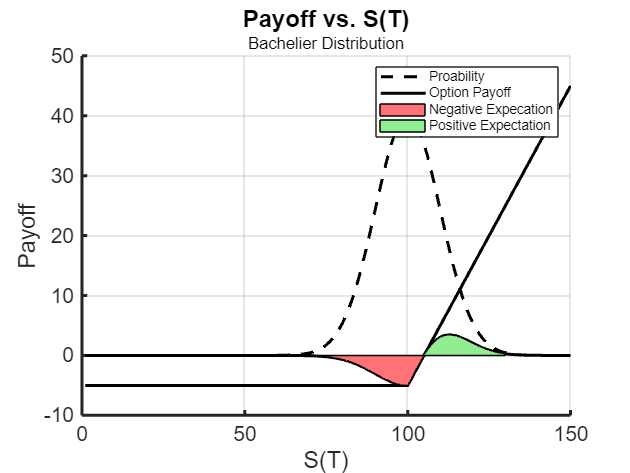

mu = 100;
sigma = 10;
prob_S = @(T) exp(-power(T-mu,2)/2/power(sigma,2));

K = 100;
c = 5;
option_payoff = @(T) max(0,T-K)-c;

expected_value = @(T) prob_S(T).*option_payoff(T);

xlabel('S(T)')
ylabel('Payoff')
title('Payoff vs. S(T)')
subtitle('Bachelier Distribution')
hold on
plot(1:150,40*prob_S(1:150),'Color',[0 0 0],'LineStyle','--') % Kentucky Windage with "Normalization"
plot(1:150,option_payoff(1:150),'Color',[0 0 0])
plot(1:150,expected_value(1:150),'Color',[0 0 0])

% Shade In Expected Value Areas

% Negative Expectation
xReds = horzcat((mu-3*sigma):.001:(K+c),flip((mu-3*sigma):.001:(K+c)));
yReds = horzcat(expected_value((mu-3*sigma):.001:(K+c)),zeros(1,length((mu-3*sigma):.001:(K+c))));
neg_patch = patch(xReds,yReds,[255,114,118]/255);

% Positive Expectation
xGreens = horzcat((K+c):.001:(mu+3*sigma),flip((K+c):.001:(mu+3*sigma)));
yGreens = horzcat(expected_value((K+c):.001:(mu+3*sigma)),zeros(1,length((K+c):.001:(mu+3*sigma))));
pos_patch = patch(xGreens,yGreens,[144,238,144]/255);
     
legend({'Proability','Option Payoff','','Negative Expecation','Positive Expectation'})
sexy_plot

neg_patch.LineWidth = 1/2;
pos_patch.LineWidth = 1/2;

real_normalization = 1/sqrt(2*pi)/sigma;
expectation_value = integral(@(T) real_normalization*expected_value(T),mu-5*sigma,mu+5*sigma)

expectation_value = -1.0106